% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["encoderB", "encoderC"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
LecturasRecto2 = readtable("C:\Users\pepeb\OneDrive\Documentos\GitHub\NanoRob_Hadrones\WRO2025\Analisis\logs\LecturasRecto.txt", opts);

% Convert to output type
encoderB = LecturasRecto2.encoderB;
encoderC = LecturasRecto2.encoderC;

% Clear temporary variables
clear LecturasRecto2

% Clear temporary variables
clear opts

error=encoderB(1:end-1)-encoderC(1:end-1);
data=encoderB(end-1:end);

vel=data(1)

vel = 0

hz=data(2)

hz = 30


tamano=size(error);

time=linspace(0,tamano(1)/hz,tamano(1));

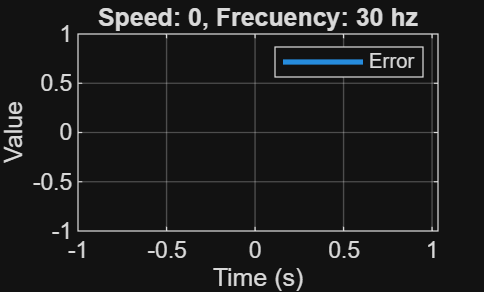

plot(time,error,LineWidth=2,Color=[0.149 0.549 0.867])
legend("Error")
title(sprintf('Speed: %.0f, Frecuency: %.0f hz', vel, hz));
xlabel('Time (s)');
ylabel('Value');
grid on